## **Tarea #1**

## **Solución**

***Pregunta 1***

Puede comprobar su resultado en precisión simple con:

[https://www.binaryconvert.com/convert_float.html](https://www.binaryconvert.com/convert_float.html)

En precisión doble con:

[https://www.binaryconvert.com/convert_double.html](https://www.binaryconvert.com/convert_double.html)

***Pregunta 2.a***

Esta es una propuesta de solución, no son necesariamente los datos del problema pero ilustran cómo puede hacerse.

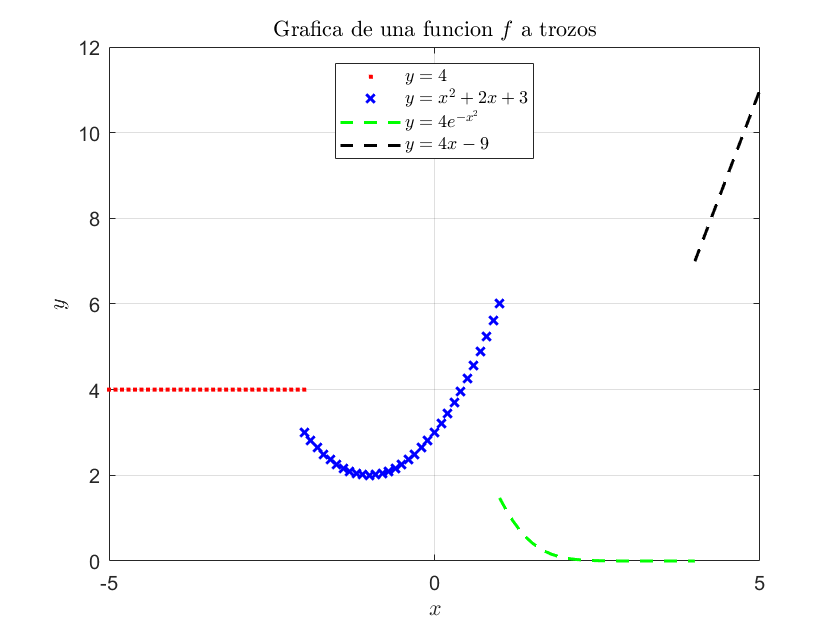

x=-5:0.1:-2;                    % primer trozo
y=4*ones(1,length(x));          % Se puede poner y=5 también
plot (x,y,'.r','linewidth',1.5)
hold on 

x=-2:0.1:1;                     % segundo trozo
y=x.^2+2*x+3;
plot(x,y,'xb','Linewidth',1.5)

x=1:0.1:4;                      % tercer trozo
y=4*exp(-x.^2);
plot(x,y,'--g','Linewidth',1.5)

x=4:0.1:5;                      % cuarto trozo
y=4*x-9;
plot(x,y,'--k','Linewidth',1.5)
hold off 
% Info de la grafica
grid on
title('Grafica de una funcion $f$ a trozos',...
    'Interpreter','latex')  % Fórmulas en LaTex
xlabel('$x$', 'Interpreter','latex')
ylabel('$y$', 'Interpreter','latex')
l=legend('$y=4$', '$y=x^2+2x+3$', '$y=4e^{-x^2}$',...
    '$y=4x-9$','Location','north');
set(l,'Interpreter','latex')

***Pregunta 2.b.***

La función tiene su código al final de este documento. Probemos con ejemplos.

Error al no cumplirse desigualdad triangular

%A=AreaTriangulo(5,6,20)

Error al tener una longitud negativa o cero.

%A=AreaTriangulo(-5,6,20)  % Aparecen comentados porque cuando
%A=AreaTriangulo(5,6,0)    % hay error no se puede seguir usando

Cálculo de una terna que sí forma un triángulo

A=AreaTriangulo(3,4,5)

A = 6

***Pregunta 3.1***

La función a elegir es $\varphi(x)=\sqrt{2+x},$ ya que puede notarse que $x_0=\sqrt{2}, \quad x_{k+1}=\varphi(x_k) = \sqrt{2+x_k}$.

Mostremos primero que $\xi=2$ es la solución:


$$$$\xi= \sqrt{2+\xi} \Rightarrow \xi^2-\xi-2=0$$
$$ \Rightarrow (\xi+1)(\xi-2)=0$$$$


Como la sucesión es de términos positivos se deduce que $\xi =2.$

Revisemos la gráfica de $\varphi(x)=\sqrt{2+x}$ en el intervalo $[1, \, 3]$, la cual es continua:

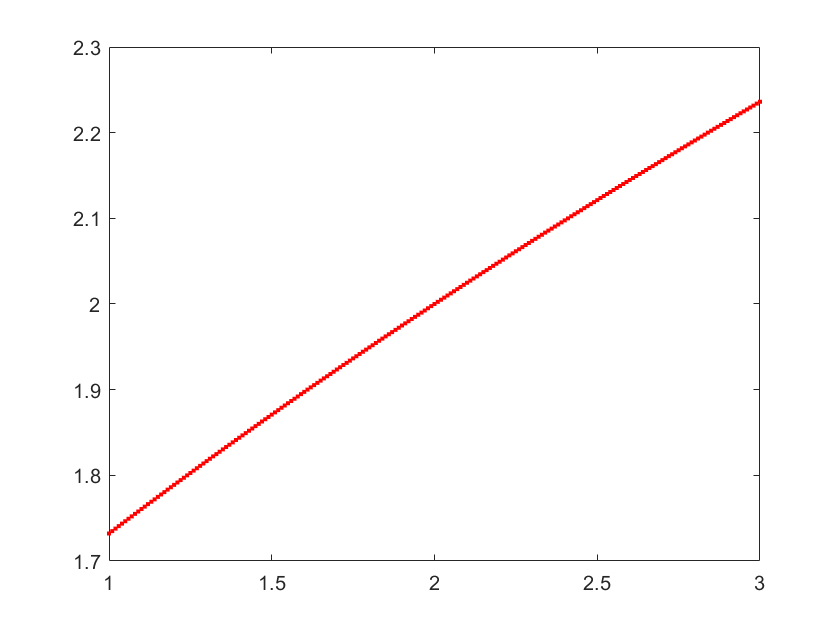

x=1:0.01:3;                     
y=sqrt(2+x);
plot(x,y,'.r','Linewidth',1.5)

Es notable que la gráfica de la función pertenece al cuadrado abierto $]1, \, 3[\,^2$ y esto comprueba que dicha función es contractiva en ese intervalo. 

Vamos a probarlo analíticamente: 


$$\varphi \prime(x) = \frac{1}{2\sqrt{2+x}} \Longrightarrow \varphi \prime \prime (x) = \frac{-1}{4(2+x)\sqrt{2+x}}$$


El signo de $\varphi \prime(x) $ siempre es positivo en $[1,3]$ y esto nos dice que dicha derivada no tiene ceros en ese intervalo, así que los valores extremos de $\varphi (x) $ se alcanzan en 

$\varphi (1)= \sqrt{3} \approx 1.73, \quad \varphi(3)=5 \approx 2.23 $, luego $\varphi([1,3]) \subset [1,3]$

El signo de $\varphi \prime \prime(x) $ siempre es negativo en $[1,3]$ y esto nos dice que dicha derivada no tiene ceros en ese intervalo, así que los valores extremos de $|\varphi \prime(x)| $ se alcanzan en 

$|\varphi \prime(1)|= \frac{1}{2\sqrt{3}} \approx 0.28, \quad |\varphi \prime(3)|=\frac{1}{2\sqrt{5}} \approx 0.22$, luego $L= |\varphi \prime(1)| = \frac{1}{2\sqrt{3}} < 1$.

Por lo tanto $\varphi(x)$ es contractiva en $[1,3].$

**Observación:** note que $\varphi(x)=x^2-x-2$ **no** nos sirve porque no es contractiva. Recuerde que la constante $L$ tiene que cumplir que $0<L<1$ en el intervalo estudiado.

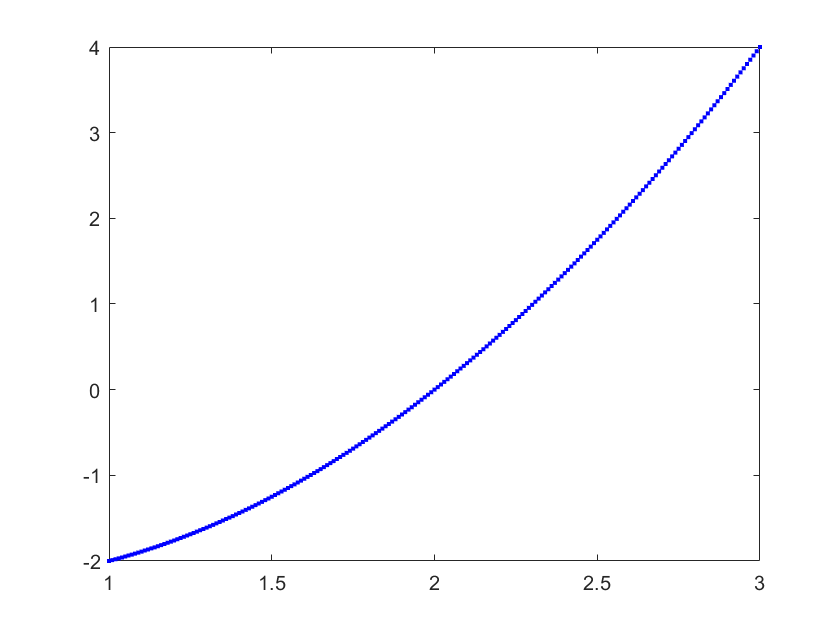

x=1:0.01:3;                     
y=x.^2-x-2;
plot(x,y,'.b','Linewidth',1.5)

Calculemos una aproximación con $\texttt{tol}=10^{-3}= \texttt{1e-3}$:

f=@(x) sqrt(2+x);
[x, k] = puntofijo(f,sqrt(2), 1e-3, 10)

x = 1.9994

k = 5

Calculamos el error relativo con respecto a la raíz exacta $\xi=2$:

e_rel=abs(2-x)/abs(2)

e_rel = 3.0118e-04

***Pregunta 3.2***

Grafiquemos $f(x)=\cos(x)-x^3$ en el intervalo $[0,1]:$

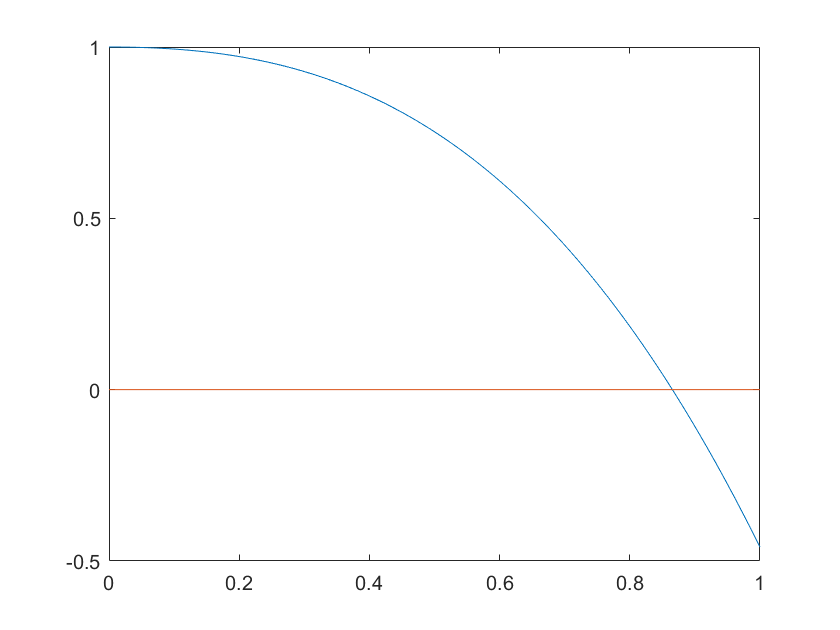

x=linspace(0,1);    
y1=cos(x)-x.^3;
y2=0*ones(1,length(x));
plot(x,y1,x,y2)

Se puede observar que hay una raíz de $f(x)$ continua en $[0,1]$, lo cual puede comprobarse usando el teorema de valores intermedios (TVI): $f(0)\cdot f(1) < 0$.

Para este ejercicio se puede utilizar un script llamado $\texttt{NewRaph1.m}$ en el que se tienen como outputs los vectores: $X$ que contiene elementos de $(x_n)$ de la sucesión de Newton-Rhapson, $Y$ que contiene elementos $(\hat{x}_n)$ de la sucesión nueva. Además se adjunta una tabla con los datos obtenidos. 

f=@(x) cos(x)-x^3;
df=@(x) -sin(x)-3*x^2;
format long; 
[X,Y] = NewRaph1(f,df,0.5, 8)

X =    0.500000000000000
   1.112141637097273
   0.909672693736807
   0.867263818208816
   0.865477135298265
   0.865474033110957
   0.865474033101614
   0.865474033101614
   0.865474033101614


Y =    0.959995724162546
   0.856027332132658
   0.865398551755202
   0.865474027715313
   0.865474033101614
   0.865474033101614
                 NaN
                   0
                   0



x_n=X;
y_n=Y;
Iter=(0:8)';

Tabla_Comparativa=table(Iter,x_n,y_n)

Tabla_Comparativa = 9×3 table
    Iter           x_n                  y_n       
    ____    _________________    _________________

     0                    0.5    0.959995724162546
     1       1.11214163709727    0.856027332132658
     2      0.909672693736807    0.865398551755202
     3      0.867263818208816    0.865474027715313
     4      0.865477135298265    0.865474033101614
     5      0.865474033110957    0.865474033101614
     6      0.865474033101614                  NaN
     7      0.865474033101614                    0
     8      0.865474033101614                    0


Vemos que la sucesión $(\hat{x}_n)$ va "más rápido" que la sucesión $(x_n).$

La forma explícita de las sucesiones (sin simplificar):


$$$$x_n= x_{n-1} - \frac{\cos(x_{n-1})-x_{n-1}^3}{-\sin(x_{n-1})-3x_{n-1}^2}$$

$$\hat{x}_n =x_{n-1} - \frac{\cos(x_{n-1})-x_{n-1}^3}{-\sin(x_{n-1})-3x_{n-1}^2} -  \frac{\left( x_{n} - \frac{\cos(x_{n})-x_{n-1}^3}{-\sin(x_{n})-3x_{n}^2} - x_{n-1} - \frac{\cos(x_{n-1})-x_{n-1}^3}{-\sin(x_{n-1})-3x_{n-1}^2}\right)^2}{x_{n+1} - \frac{\cos(x_{n+1})-x_{n+1}^3}{-\sin(x_{n+1})-3x_{n+1}^2} -2\left( x_{n} - \frac{\cos(x_{n})-x_{n}^3}{-\sin(x_{n})-3x_{n}^2}\right) + x_{n-1} - \frac{\cos(x_{n-1})-x_{n-1}^3}{-\sin(x_{n-1})-3x_{n-1}^2}}$$ $$


## Funciones

Area de triángulo

function [A]=AreaTriangulo(a,b,c)
p=(a+b+c)/2;        % El semiperímetro
%A=0;
if a<=0 || b<=0 || c<=0  %Revisando si hay entradas no positivas
    error('Al menos una de las longitudes es negativa o nula')
%    return         %parece que no es necesario usarlo
elseif a>=b+c || b>a+c || c>=a+b % Negación de la desigualdad triangular
    error('No se cumple desigualdad triangular')
%    return         %parece que no es necesario usarlo
else 
    A = sqrt(p*(p-a)*(p-b)*(p-c));
end 
end

Script para punto fijo

function [x, k] = puntofijo(f,x0, tol, iterMax)
    k = 0;
    x = x0;
    err = tol+1;
    while k < iterMax && err > tol
        x = f(x);
        err = abs(x-x0)/abs(x);     %error relativo
        x0 = x;
        k = k+1;  
    end
end

Script para Newton-Rhapson con la sucesión de Aitken:

function [X,Y] = NewRaph1(f,df,x0, iter)
k = 0;
x = x0;
X=zeros(iter+1,1);  %Acá guardamos los x_k de la sucesión de Newton-Rhapson
Y=zeros(iter+1,1);  %Acá guardamos los x_k techo de la sucesión acelerada
    while k < iter
        q = df(x);
            if q==0
                disp('Se anula la derivada')
            end
        x = x-f(x)/q;
        X(1)=x0;
        X(k+2)=x;
        k = k+1;  
    end
    Y(1)=X(1)-(X(2)-X(1))^2/(X(3)-2*X(2)+X(1));
    for i=2:length(X)-1
        Y(i-1)=X(i-1)-(X(i)-X(i-1))^2/(X(i+1)-2*X(i)+X(i-1));
    end
    
end